clc
clear
close all
syms d


a = 1 - 1.4*d + 0.4*d^2;
b = 0.2*d + 0.1*d^2;

S = b/a

$$S = \frac{\frac{d^{2}}{10}+\frac{d}{5}}{\frac{2\,d^{2}}{5}-\frac{7\,d}{5}+1}$$

g = 1;
f = 1-d;
W = g/f;


[xmin,y]=axminbyc(f,b,g,d)

$$xmin = \frac{d}{3}+1$$

$$y = \frac{10}{3}$$

E = xmin

$$E = \frac{d}{3}+1$$

U = simplify(y*a/f)

$$U = \frac{10}{3}-\frac{4\,d}{3}$$

syms z
E = simplify(subs(E,d,z^(-1)))

$$E = \frac{1}{3\,z}+1$$

[num,den] = numden(E)

$$num = 3\,z+1$$

$$den = 3\,z$$

num = sym2poly(num)

num =      3     1


den = sym2poly(den)

den =      3     0


num = num./den(1)

num =     1.0000    0.3333


den = den./den(1)

den =      1     0


E = tf(num,den,1)

E =
 
  z + 0.3333
  ----------
      z
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


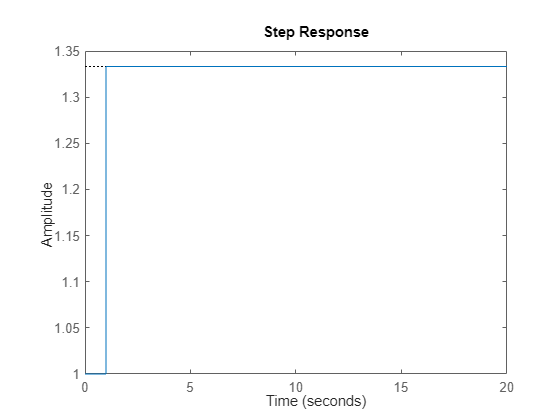

step(E)